# Steady-State Water Quality Model Formulation | BWFLNet

#### Prepared by: Bradley W Jenks

#### Date: 31 October 2021

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
run([epanet_path,'\start_toolkit']);

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet('BWFLnet_Sept2021.inp');

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_Sept2021.inp"...
Input File "BWFLnet_Sept2021.inp" loaded sucessfuly.


Next, model data is extracted into Matlab variables from the network using a pre-formulated function, 'model_data,' created by the InfraSense Labs research group. Additional matrices are formed for input into the hydraulic solver, which is subsequently discussed.

% File name where 
data_filename = 'BWFLnet_SS';
% Call function and generate matlab data structure from network
% Creation of the data structure is done in a separate matlab script to keep the current simulation clear and concise
modeldata = load(data_filename,'demands','H0');

Error using load
Unable to find file or directory 'BWFLnet_SS'.


% Note that model demands are modified to be constant over simulation
% duration; this is to compare SS WQ results


% The next function organises network data into variables readable by the
% research group's hydraulic solvers, which is saved in the 'model' 
model = model_data(data_filename);
eta = zeros(model.np,model.nt);
model.A13 = sparse(model.np,model.np);

Operational parameters reflecting model demands and known heads (i.e., reservoirs) are then added.

d = modeldata.demands; % m^3/s
h0 = modeldata.H0;

### Hydraulic Simulation

Now that the network data is extracted from the EPANET input file and any additional variables are created, hydraulic simulation using the operational data called above is performed. A null space hydraulic solver developed by the InfraSense Labs research group is utilised, where its corresponding Matlab code is stored in a separate function. The 'hydraulic simultion' function is called below, with the following inputs: operational demand and known heads, the 'model' data structure which stores the relevant network properties, and a precursor array, 'eta,' necessary if pressure reducing valve controls are modelled.

[Q,H,iter] = hydraulic_simulation(d,h0,eta,model); 

To ensure the results replicate those of EPANET's solvers, results from EPANET are called and compared from the database structure here.

load(data_filename,'H_epanet','Q_epanet');

fprintf('Maximum difference in simulated hydraulic heads = %d m',max(max(abs(H-H_epanet))))

Maximum difference in simulated hydraulic heads = 1.008704e-03 m

fprintf('Maximum difference in simulated flows = %d m^3/s',max(max(abs(Q-Q_epanet))))

Maximum difference in simulated flows = 2.773176e-06 m^3/s

Results of the hydraulic simulation then inform the flow direction in the A12 matrix in order to create a directed graph of the network. A directed graph, based on flow direction, is required as an input for the modelling of distribution water quality.

% Sort A12 matrix based on flow direction from hydraulic results
model.A12 = full(model.A12);
for aa = 1:model.nt
    A12_d(:,:,aa) = model.A12;
end

for ii = 1:model.nt
for jj = 1:model.np
    w = find(A12_d(jj,:,ii) == -1);
    z = find(A12_d(jj,:,ii) == 1);
    if Q(jj,ii) < 0
        A12_d(jj,w,ii) = 1;
        A12_d(jj,z,ii) = -1;
    end
end
end

% Save reorganised A12 matrix to model dataframe
model.A12_d = A12_d; % Save new 3 dimensional incidence matrix
% load(data_filename,'A12');

% Quick check (for t = 1) to ensure A12 matrix has been modified appropriately
tf = isequal(model.A12_d(:,:,1),model.A12)

tf = logical
   0


The absolute value of flow rates simulated previously are now applied and are the correct flow direction for each time step according to the A12_d matrix. 

### Directed Network Graph and Plotting Framework

Enter text here...

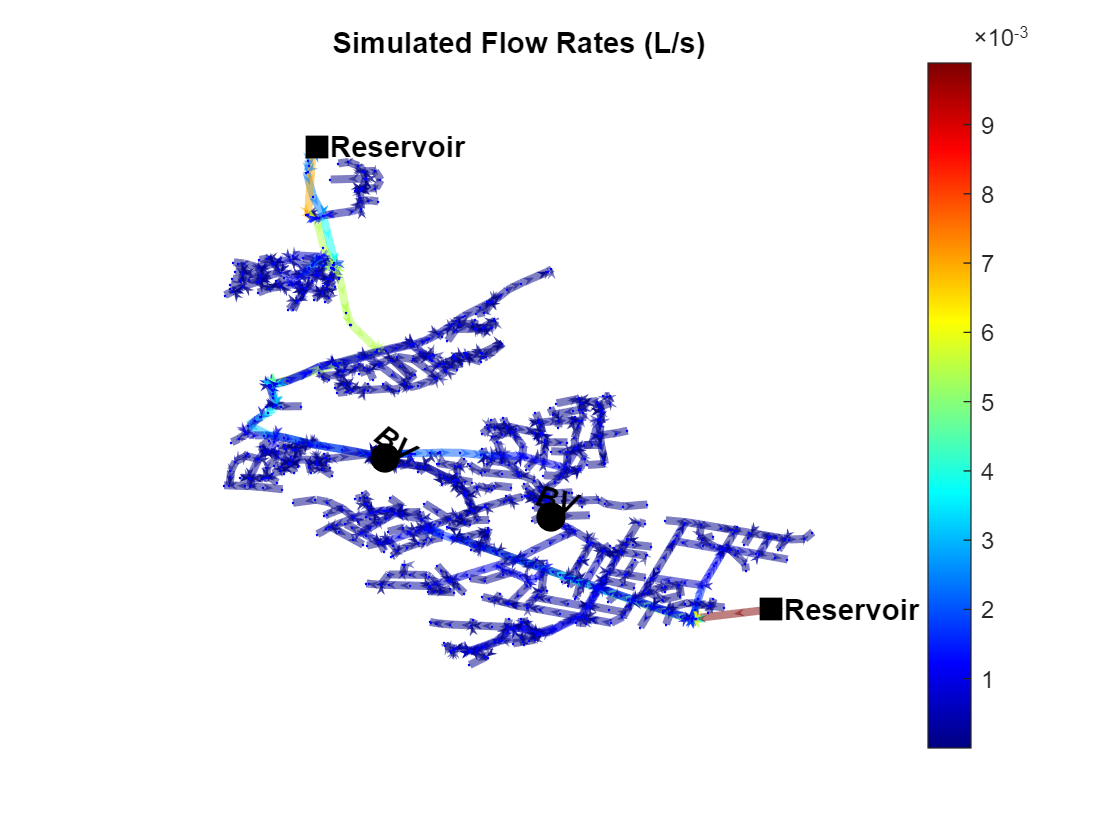

% Create and plot network graph; this calls an addition 'PlotNetworkData' function
t = 1; % Select arbitrary timestep for plot and steady-state WQ model
[p1,G1,edgemap] = PlotNetworkEdge(model,t,Q);

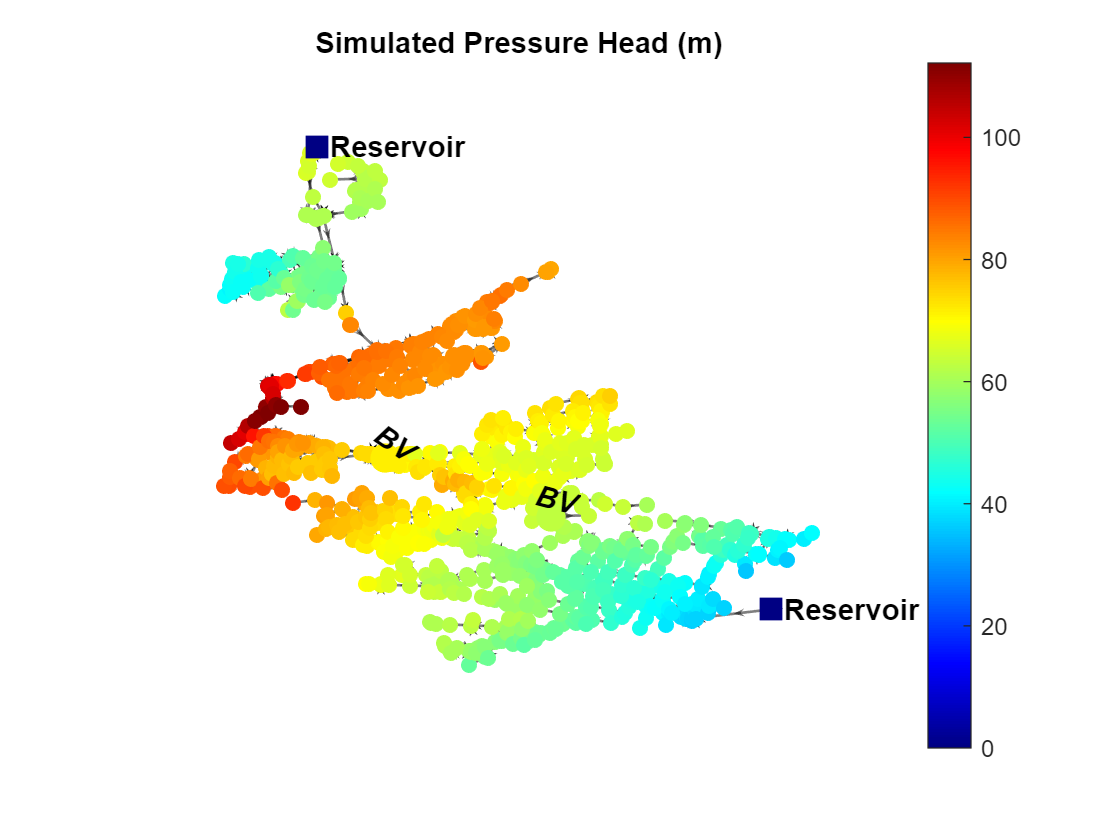

[p2,G2] = PlotNetworkNode(modeldata,model,t,H);

### Water Quality Simulation and Calibration

#### Steady-State Model Formulation

The following code begins/attempts to formulate the solution to a steady-state water quality model. Formulation of a dynamic (extended period simulation; EPS) model will be developed subsequent to successful implementation of its steady-state variety.

% Topographic sorting algorithm 
T_i = toposort(p1).';
T_ii = toposort(p1,'order','stable').';
tf = isequal(T_ii,T_i)

tf = logical
   0


T = T_ii;
for s = 1:size(model.ReservoirIdx,2)
    a = find(T(:,1) == model.ReservoirIdx(:,s));
    T(a,:) = []; % delete reservoir (source) nodes
end

% Create flow contribution/distribution matrix, psi (Note: demand set to t = 1 hr for now...)
% Vector representing diagnonals of psi matrix - sum of outflow to other nodes and from demands
psi_D = zeros(size(T,1),1);
p1_array = table2array(p1.Edges);
for kk = 1:size(T,1)
    a = find(p1_array(:,1) == T(kk,1));
    b = p1_array(a,3);
    psi_D(kk,:) = sum(b,1) + modeldata.demands(T(kk,1),t);
end

% For loop assigning flow contribution/distribution relationships (column then row hierarchy)
% Muliply cell values by e^(k*tau) for first-order disinfectant decay model
% Initialise vector of chlorine decay coefficients, k (all forms are considered here as an all-encompassing coefficient)
% Initialise vector of pipe travel times for the modelling of disinfectant decay

p1_array = [p1_array ones(model.np,2)]; % Append two new columns to assign disinfectant decay coefficients and travel times
kd = ones(model.np,1).*-0.25; % value selected arbitrarily
kd(model.IndexValves,:) = 0; % set values across valve links to 0
tau = model.L.*(abs(Q(:,t))).^-1.*(model.D.^2.*0.25.*pi)./86400; % travel time in days
tau(model.IndexValves,:) = 0;

for j = 1:model.np
    s = find(p1_array(:,4) == j);
    p1_array(s,5) = kd(j,1);
    p1_array(s,6) = tau(j,1);
end

% Create flow contribution/distribution matrix
psi = zeros(size(T,1),size(T,1));
for i = 1:size(T,1)
    a = T(i,1);

    for j = 1:size(T,1)
        b = T(j,1);
        c = find(p1_array(:,1) == a & p1_array(:,2) == b);

        if a == b
            psi(j,i) = psi_D(j,1);

        elseif ~isempty(c)
            psi(j,i) = -1.*p1_array(c,3).*exp(p1_array(c,5).*p1_array(c,6));
            
        end
    end
end

% Create vector of unknown node concentrations
C = ones(size(T,1));

% Create vector for equation RHS (source or mass injection nodes)
for k = 1:size(model.ReservoirIdx,2)
    s_idx(k,:) = find(p1_array(:,1) == model.ReservoirIdx(1,k));
end

gamma_s_node = p1_array(s_idx,2).';
gamma_s_Q = p1_array(s_idx,3);
gamma_s_dec = exp(p1_array(s_idx,5).*p1_array(s_idx,6));

gamma = zeros(size(T,1),1);
for j = 1:size(gamma_s_node,2)
    a(j,:) = find(T(:,1) == gamma_s_node(1,j));
end

% Load (or set) source quality values to be multiplied to gamma vector to form RHS of equation
load(data_filename,'s_qual');
s_C = s_qual(1,model.ReservoirIdx).';

% Form final gamma vector
gamma(a,1) = gamma_s_Q.*gamma_s_dec.*s_C;

% Steady-state WQ solution using Matlab linsolve (or mldivide)
C = psi\gamma;
% Need to then sort values back to plotting table, which is currently by
% junction index; source concentrations then added at reservoirs
C_ss = zeros(model.nn + model.n0,1);
for i = 1:model.nn
    g = find(i == T(:,1));
    C_ss(i,1) = C(g,1);
end
for j = model.nn + 1:model.nn + model.n0
    C_ss(j,1) = s_qual(1,j);
end

Results of the steady-state water quality analysis are plotted below.

%[p2,G2] = PlotNetworkNode(modeldata,model,t,C);

To ensure results of the modelling work are compatible with those of EPANET's solvers, a simulation of 7 days is performed in EPANET.

% 7-day EPANET water quality simulation
net.setQualityType('Chlorine','mg/L');
net.setNodeSourceQuality(s_qual);

% Use this to specify the hydrualic and water quality time steps (in seconds)
net.setTimeQualityStep(5*60); 
net.setTimeHydraulicStep(60*60);
days = 20;
net.setTimeSimulationDuration(days*net.getTimeSimulationDuration);

% Set constant demands for EPANET SS WQ simulation
load(data_filename,'Patterns_SSb','JunctionIdx');
net.setPatternMatrix(Patterns_SSb);

% Set decay coefficients
net.setLinkBulkReactionCoeff(kd);
net.setOptionsPipeBulkReactionOrder(1);
% Initial quality keep at zero

% Run EPANET WQ simulate and extract results
EPANET_qual = net.getComputedQualityTimeSeries;
c_nodes = EPANET_qual.NodeQuality';
% Compare concentration between EPANET and Matlab code 
C_ss_diff = C_ss - mean(c_nodes(:,360:end),2); % Mean of last 5 days in simulation

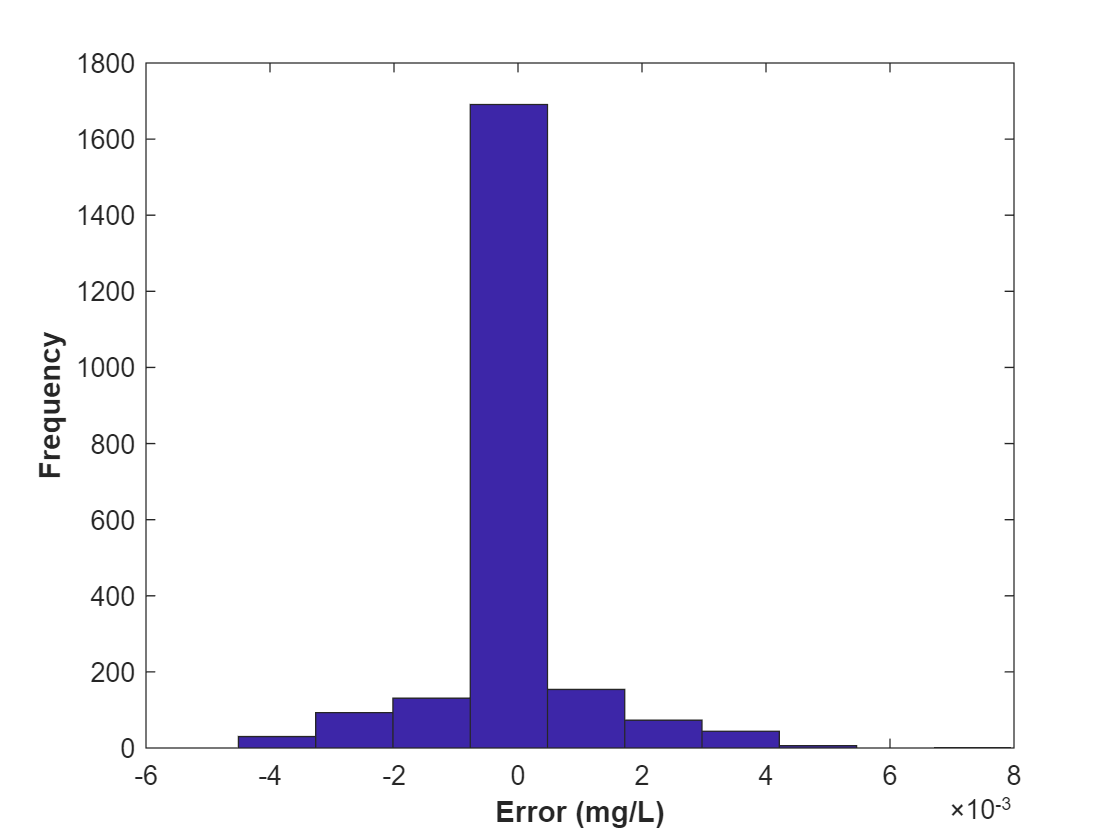

% Error histogram and example for Junction C
figure
hist(C_ss_diff)
xlabel('Error (mg/L)','FontWeight','bold')
ylabel('Frequency','FontWeight','bold')

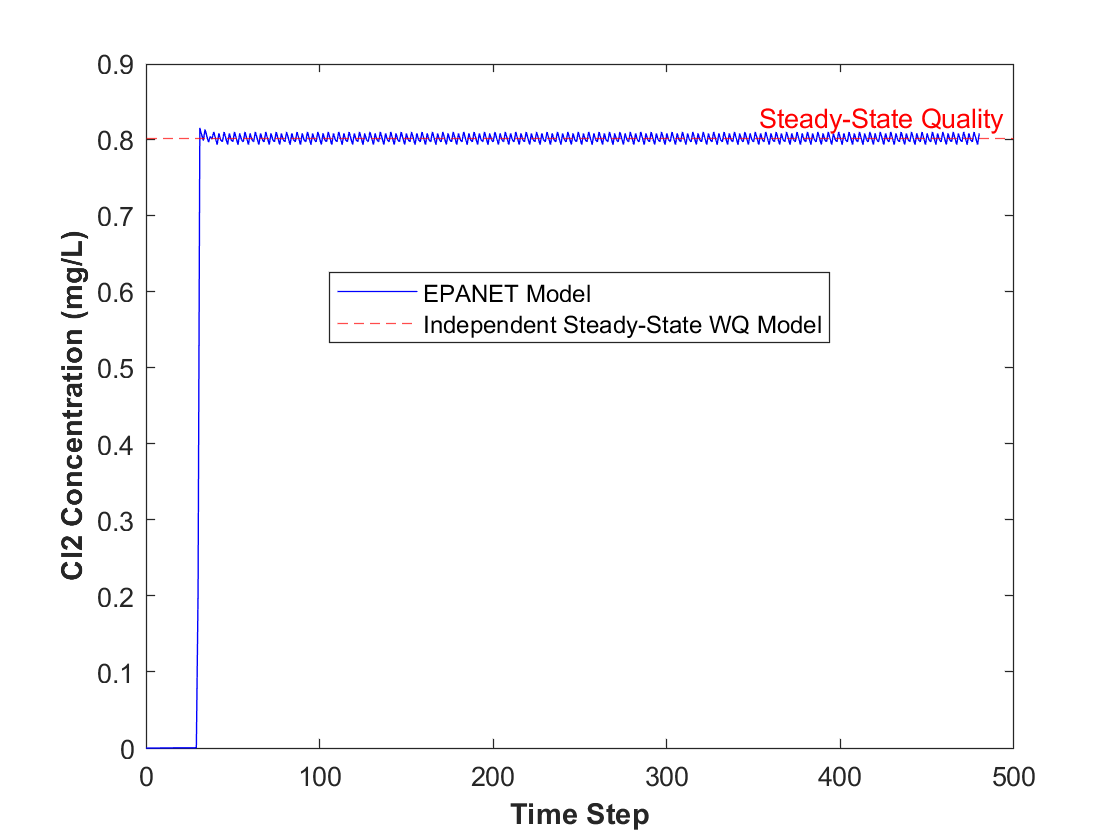

figure
plot(0:days*24,c_nodes(3,:)','-b')
hold on
yline(C_ss(3,1),'--r','Steady-State Quality')
hold off
xlabel('Time Step','FontWeight','bold')
ylabel('Cl2 Concentration (mg/L)','FontWeight','bold')
legend('EPANET Model','Independent Steady-State WQ Model','location','best')

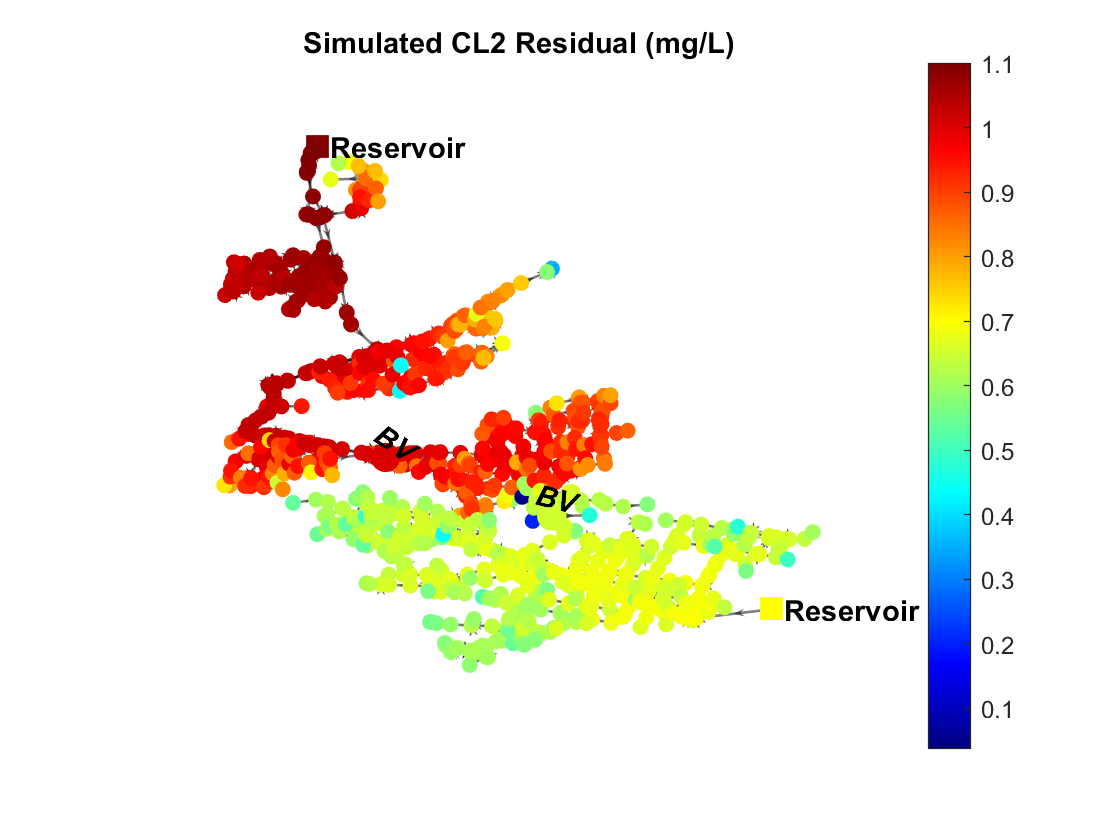

% Plot Cl2 distribution
figure
[p3,G3] = PlotNetworkNode(modeldata,model,t,C_ss);

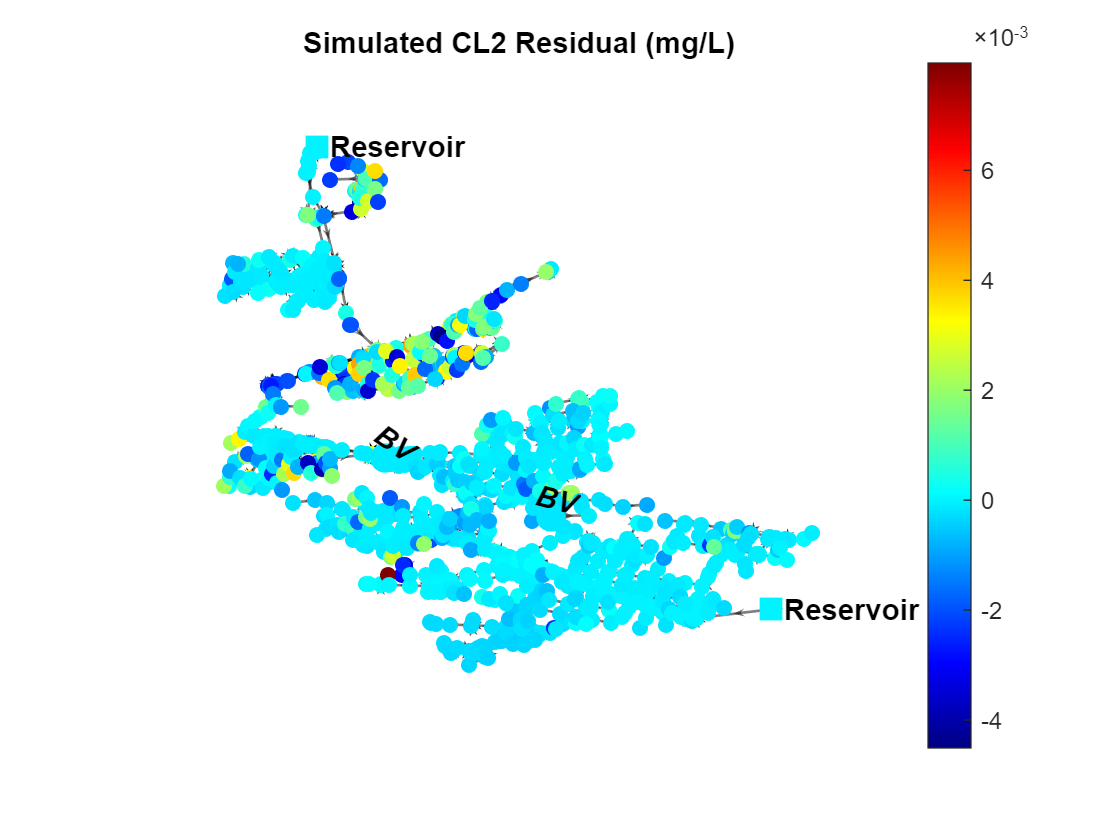

% Plot Cl2 difference across network
figure
[p4,G4] = PlotNetworkNode(modeldata,model,t,C_ss_diff);